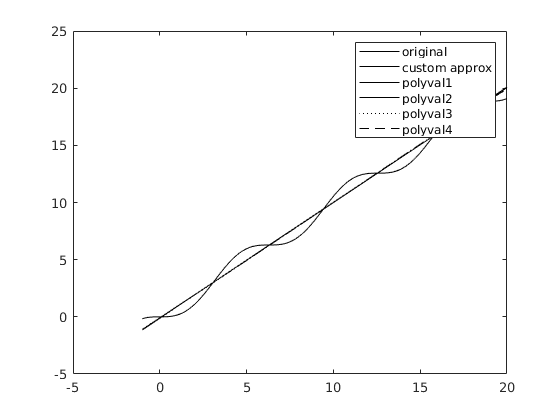

F = @(t) (t-sin(t));
x = -1:1e-1:20; % исходный вектор аргументов -1:.2:2
y = F(x); % исходный вектор аргументов 
plot(x, y, '-k');
hold on;

%Расчёт полинома методом наименьших квадратов
syms a1 a2 a3 %обяьвления символьных переменных
%обявление уравнений для решения системы уравнений
f1 = a1*length(x)+a2*sum(x)+a3*sum(x.^2)==sum(y);
f2 = a1*sum(x)+a2*sum(x.^2)+a3*sum(x.^3)==sum(x.*y);
f3 = a1*sum(x.^2)+a2*sum(x.^3)+a3*sum(x.^4)==sum(x.^2.*y);

sol = solve(f1,f2,f3); %решение системы уравнений

a1=double(sol.a1);
a2=double(sol.a2);
a3=double(sol.a3);
%расчет значений полиномов для заданных значений
custom_approx = a1+a2.*x+a3.*x.^2;
plot(x, custom_approx, '-k');
hold on;

%Расчёт полинома 1 порядка посредством втроенных функции matlab
var_polyfit1 = polyfit(x,y,1);
var_polyval1 = polyval(var_polyfit1,x);
plot(x, var_polyval1, '-k');
hold on;

%Расчёт полинома 2 порядка посредством втроенных функции matlab
var_polyfit2 = polyfit(x,y,2);
var_polyval2 = polyval(var_polyfit2,x);
plot(x, var_polyval2, '-k');
hold on;

%Расчёт полинома 3 порядка посредством втроенных функции matlab
var_polyfit3 = polyfit(x,y,3);
var_polyval3 = polyval(var_polyfit3,x);
plot(x, var_polyval3, ':k');
hold on;

%Расчёт полинома 4 порядка посредством втроенных функции matlab
var_polyfit4 = polyfit(x,y,4);
var_polyval4 = polyval(var_polyfit4,x);
plot(x, var_polyval4, '--k');
legend('original','custom approx','polyval1','polyval2','polyval3','polyval4');
hold off;